## Project 2: Calculating Values at Risk

### 1.

Let the log returns $X$ be given by $X_t =\log \left(V_t \right)-\log \left(V_{t-1} \right)$. Let $F_{X_t } =P\left(X_t \le \cdot \left|\left(X_s ,V_s ,s<t\right)\right.\right)$ be the cumulative distribution function of $X_t$ given all information up to time $t-1$. Show that


$${\textrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)$$



$$p=P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)$$



$$F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=p\right\rbrace$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right.\right.\right)\right\rbrace$$


Above, $\left\lbrace x:y\right\rbrace$is read as "$x$ such that $y$ holds"


$$\begin{array}{l}
X_t =\log \left(V_t \right)-\log \left(V_{t-1} \right)\\
\;\;\;\;=\log \left(\frac{V_t }{V_{t-1} }\right)\\
e^{X_t } =\frac{V_t }{V_{t-1} }\\
V_{t-1} \left(e^{X_t } -1\right)=V_t -V_{t-1} 
\end{array}$$



$$\begin{array}{l}
P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)=P\left(V_{t-1} \left(e^{X_t } -1\right)\le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)=P\left(e^{X_t } \le \frac{{\textrm{VaR}}_t }{V_{t-1} }+1\left|\;\left(V_s ,s<t\right)\right.\right)\\
=P\left(X_t \le \log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(X_t \le \log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:x=\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\right\rbrace =\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\\
e^{F_{X_t }^{-1} \left(p\right)} =\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\\
{\textrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)
\end{array}$$


### 2.

Plot the (sample) autocorrelation and partial autocorrelation functions of X for lags h = 0,...,50

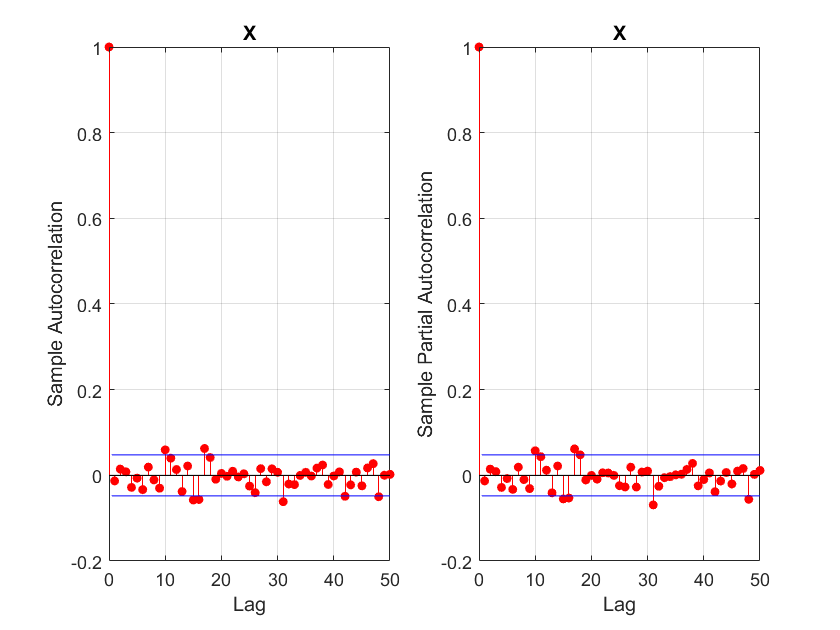

close all
V = readtable('dat_intel.csv');
X = log(V.Close(2:end)) - log(V.Close(1:end-1));

subplot(1,2,1);
autocorr(X,'NumLags',50);
title('X');
ylim([-.2, 1]);
xlim([0, 50]);
subplot(1,2,2);
parcorr(X,'NumLags',50);
title('X');
ylim([-.2, 1]);
xlim([0, 50]);

No large sized lags, but their still more than 5% of the lags that are outside the boundaries, indicating that the data is not only noise.

Then, do a Ljung–Box test with h = 50 for X

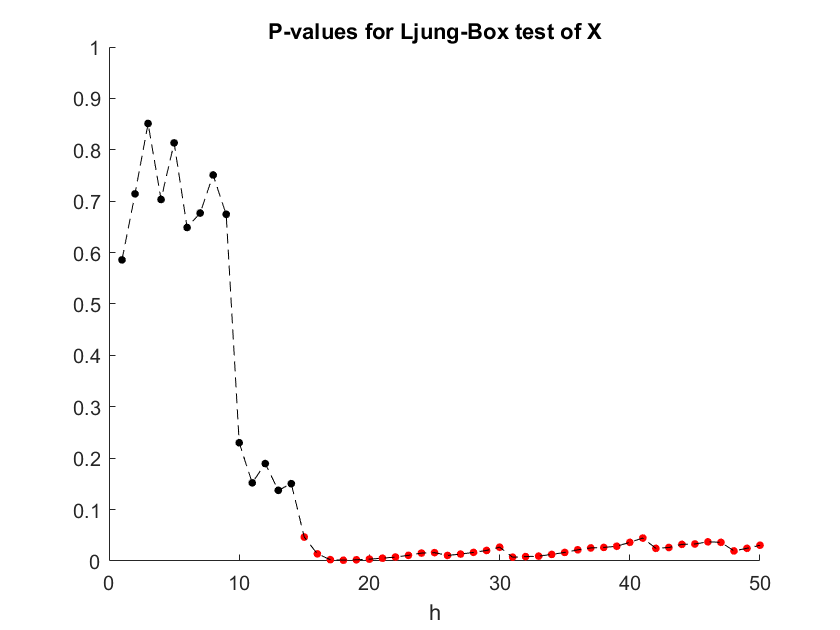

alpha = .05;
lags = 1:50;
close all
[h, pValues, stat, cValue] = lbqtest(X, 'lags', lags);

c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled');
hold on
plot(lags, pValues, 'k--')
hold off
ylim([0, 1]);
xlim([0,50]);
title('P-values for Ljung-Box test of X');
xlabel('h');

if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


Repeat these two steps with the squared returns $X^2$. We start with the (sample) autocorrelation and partial autocorrelation functions of $X^2$ for lags h = 0,...,50

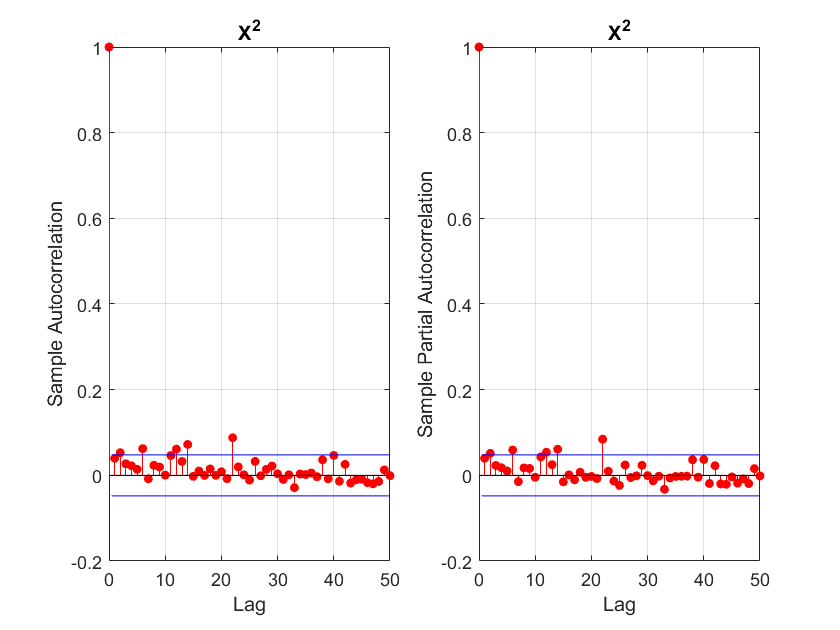

subplot(1,2,1)
autocorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])
subplot(1,2,2)
parcorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])

We can see that their are some larger sized lags, and that there is more than 5% of the lag that are outside the boundaries, indicating that the data is not only noise.

do a Ljung–Box test with h = 50 for X^2

close all
[h, pValues, stat, cValue] = lbqtest(X.^2, 'lags', lags, 'Alpha', alpha);
c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled');
hold on
plot(lags,pValues,'k--')
hold off
ylim([0, 1])
title('P-values for Ljung-Box test of X^2')
xlabel('h')
if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


#### Discussion

Both $X$ and $X^2$ (the squared returns) have outliers on the autocorrelation function plots. For both $X$ and $X^2$ we reject the Ljung-Box null hypotheses that $X$ and $X^2$ are realizations of $\textrm{IID}\left(\mu \;,\sigma {\;}^2 \right)$ at the 5% level for $h=50$. This means we might be able to tease out relationships among the data, as they are likely not entirely white noise.

### 3)

Now split the time series $X$ into a training set ($X_t$ , t = 2,...,1526) and a test set ($X_t$ , t = 1527, . . . , 1751).

trainX = X(2:1526);
testX = X(1527:1750);

####     3. Gaussian distribution

    For all values of p and q in the range 0, 1, . . . , 15 and such that p+q > 0 and p ≥ q, fit an ARMA(p, q) process with Gaussian noise to the square returns obtained from the training data and compute the BIC and the AICC (this will take a couple of minutes). Which models minimize the two information criteria? 

i=1;
clear pq mdl logL numParam WN_variance_MLE EstMdl
pq = [];
for p = 0:15
    for q = 0:15
        if p+q>0 && p>=q
            mdl(i) = arima(p, 0, q);
            mdl(i).Constant = mean(trainX.^2);
            pq = [pq,  [p; q]];
            i = i + 1;
        end
    end
end
p = pq(1,:);
q = pq(2,:);

Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
for i = 1:length(mdl)
    [EstMdl(i), ~, logL(i)] = estimate(mdl(i),trainX.^2,'Display','off','Options',Options);
    results = summarize(EstMdl(i));
    numParam(i) = sum(results.Table.Value ~= 0) - 1; % =M from hints (-1 to remove variance)
    WN_variance_MLE(i) = results.VarianceTable.Value; % maximum likelihood estimate of white noise variance
end
AICC = calculateAICC(length(trainX), numParam, logL); % both defined at end of file
BIC = calculateBIC(length(trainX), p, q, WN_variance_MLE, trainX.^2, numParam, 'M');
i_AICC = find(AICC == min(AICC));
i_BIC = find(BIC == min(BIC));
disp(["Model which minimizes [BD]'s AICC:" mdl(i_AICC).Description; "Model which minimizes [BD]'s BIC:" mdl(i_BIC).Description])

    "Model which minimizes [BD]'s AICC:"    "ARIMA(2,0,2) Model (Gaussian Distribution)"
    "Model which minimizes [BD]'s BIC:"     "ARIMA(2,0,2) Model (Gaussian Distribution)"



best_ARMA_mdl_Gauss_AICC = EstMdl(i_AICC);
best_ARMA_mdl_Gauss_BIC = EstMdl(i_BIC);
max_order_Gauss = max([p([i_AICC, i_BIC]) q([i_AICC, i_BIC])]);

####     3. Student’s *t *distribution

i = 1;
clear pq mdl logL numParam WN_variance_MLE EstMdl
pq = [];
for p = 0:15
    for q = 0:15
        if p+q>0 && p>=q
            mdl(i) = arima(p,0,q); 
            mdl(i).Constant = mean(trainX.^2);
            mdl(i).Distribution="t";
            pq = [pq,  [p; q]];
            i = i + 1;
        end
    end
end
p = pq(1,:);
q = pq(2,:);

Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
for i = 1:length(mdl)
    try
        [EstMdl(i),~,logL(i)] = estimate(mdl(i),trainX.^2,'Display','off','Options', Options);
        results = summarize(EstMdl(i));
        numParam(i) = sum(results.Table.Value ~= 0) - 2; % = M from hints (-2 to remove DoF and variance)
        WN_variance_MLE(i) = results.VarianceTable.Value; % maximum likelihood estimate of white noise variance
    catch
        disp("error")
        disp(mdl(i).Description)
        disp("")
    end
end
AICC = calculateAICC(length(trainX), numParam, logL); % both defined at end of file
BIC = calculateBIC(length(trainX), p, q, WN_variance_MLE, trainX.^2, numParam, 'M');
i_AICC = find(AICC == min(AICC));
i_BIC = find(BIC == min(BIC));
disp(["Model which minimizes [BD]'s AICC:" mdl(i_AICC).Description; "Model which minimizes [BD]'s BIC:" mdl(i_BIC).Description])

    "Model which minimizes [BD]'s AICC:"    "ARIMA(3,0,2) Model (t Distribution)"
    "Model which minimizes [BD]'s BIC:"     "ARIMA(3,0,2) Model (t Distribution)"



best_ARMA_mdl_t_AICC = EstMdl(i_AICC);
best_ARMA_mdl_t_BIC = EstMdl(i_BIC);
max_order_t = max([p([i_AICC, i_BIC]) q([i_AICC, i_BIC])]);

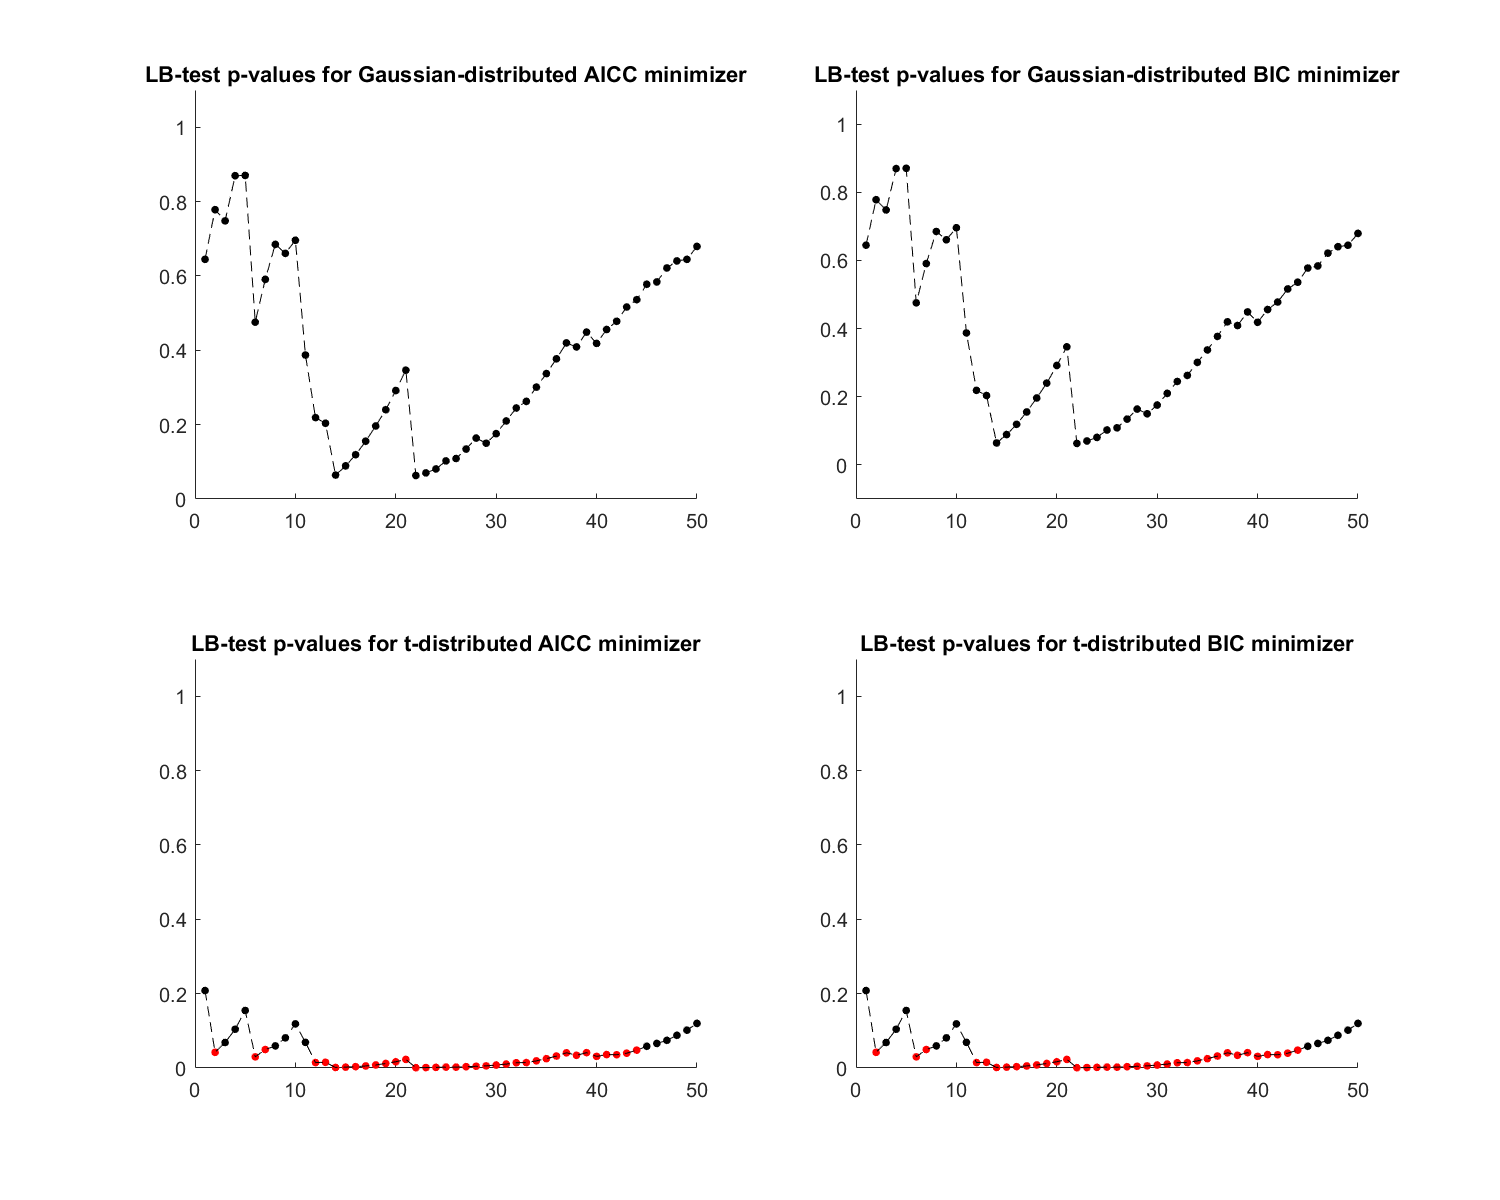

[res_Gauss_AICC, v_Gauss_AICC] = infer(best_ARMA_mdl_Gauss_AICC, trainX.^2);
[res_Gauss_BIC, v_Gauss_BIC] = infer(best_ARMA_mdl_Gauss_BIC, trainX.^2);
[res_t_AICC, v_t_AICC] = infer(best_ARMA_mdl_t_AICC, trainX.^2);
[res_t_BIC, v_t_BIC] = infer(best_ARMA_mdl_t_BIC, trainX.^2);

res_Gauss_AICC = res_Gauss_AICC ./ sqrt(v_Gauss_AICC);
res_Gauss_BIC = res_Gauss_BIC ./ sqrt(v_Gauss_BIC);
res_t_AICC = res_t_AICC ./ sqrt(v_t_AICC);
res_t_BIC = res_t_BIC ./ sqrt(v_t_BIC);

lags = 1:50;
close all
set(gcf,'Position',[100, 100, 1000, 800])

subplot(2,2,1)
[h, pValues, stat, cValue] = lbqtest(res_Gauss_AICC, 'lags', lags);
c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled')
hold on
plot(lags, pValues, 'k--')
hold off
ylim([0 1.1])
title('LB-test p-values for Gaussian-distributed AICC minimizer')

subplot(2,2,2)
[h, pValues, stat, cValue] = lbqtest(res_Gauss_BIC, 'lags', lags);
c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled')
hold on
plot(lags, pValues, 'k--')
hold off
ylim([-0.1 1.1])
title('LB-test p-values for Gaussian-distributed BIC minimizer')

subplot(2,2,3)
[h, pValues, stat, cValue] = lbqtest(res_t_AICC, 'lags', lags);
c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled')
hold on
plot(lags, pValues, 'k--')
hold off
ylim([0 1.1])
title('LB-test p-values for t-distributed AICC minimizer')

subplot(2,2,4)
[h, pValues, stat, cValue] = lbqtest(res_t_BIC, 'lags', lags);
c = (pValues < .05)' .* [1 0 0];
scatter(lags', pValues', 15, c, 'filled')
hold on
plot(lags, pValues, 'k--')
hold off
ylim([0 1.1])
title('LB-test p-values for t-distributed BIC minimizer')

There are no statistically significant p-values up to h=50 for the Gaussian distributed ARMA residuals, so we do not reject the null hypothesis that the residuals are IID noise.

For the t-distribution we have many statistically significant p-values, for each of which we reject the null hypothesis. This means our residuals for these lags are not entirely white noise, and we may be able to further tease out relationships.

Under the assumption that the GARCH process $E\left(\sigma_t^4 \right)<\infty$ a $X^2 =\left(X_t^2 ,t\in Z\right)\sim \textrm{ARMA}\left(\max \left\lbrace p,q\right\rbrace ,q\right)$, so by looking in the reverse direction of this, on the four best ARMA models found, we can deduce four GARCH models that might be suitble model for the data;

`ARMA gaussian distribution AICC and BIC: ARMA(3,2) `$\Rightarrow$`GARCH(3,2)`

`ARMA Student’s t AICC: ARMA(2,2) `$\Rightarrow$`GARCH(2,2), GARCH(1,2) (as we do not know if p or q is the maximum)`

`ARMA Student’s t BIC: ARMA(3,2) `$\Rightarrow$`GARCH(3,2)`

ARMA_to_GARCH_Gauss_params = struct('p',[1 2],'q',[1 2]);
ARMA_to_GARCH_t_params = struct('p',[1 2],'q',[1 2]);

### 4)

Let $K$be the maximal order of the ARMA models with Gaussian noise fitted in the previous task. For all values of $p$ and $q$ such that $0<p\le K$ and $0\le q\le K,$ fit a $\textrm{GARCH}\left(p,q\right)$ process driven by Gaussian noise to the training data and compute the BIC and AICC (this will take a couple of minutes). Which models minimize the two information criteria? Write these candidate models down including the assumption on the noise.

clearvars EstMdl numParam_garch logL_garch
Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
i = 1;
K = max_order_Gauss; %max(q,p) of the gaussian models in task 3
qp_garch = [];
for p = 1:K
    for q = 1:K
        mdl_temp = garch('GARCHLags',1:q,'ARCHLags',1:p,'Offset',mean(trainX.^2));
        mdl_temp.Offset = mean(trainX);
        [EstMdl(i), ~, logL_garch(i), ~] = estimate(mdl_temp, trainX, 'Display', 'off', 'Options', Options);
        results = summarize(EstMdl(i));
        numParam_garch(i) = sum(results.Table.Value ~= 0) - 1; % subtract the user-defined offset
        qp_garch = [qp_garch,  [q; p]];
        i = i + 1;
    end
end
q_garch = qp_garch(1,:);
p_garch = qp_garch(2,:);

AICC_garch = calculateAICC(length(trainX), numParam_garch, logL_garch); % defined at end of file
BIC_garch = -2*logL_garch + numParam_garch*log(length(trainX));

i_AICC = find(AICC_garch==min(AICC_garch));
i_BIC = find(BIC_garch==min(BIC_garch));

best_GARCH_mdl_Gauss_AICC = EstMdl(i_AICC);
best_GARCH_mdl_Gauss_BIC = EstMdl(i_BIC);

    "Model which minimizes [BD]'s AICC:"    "GARCH(2,2) Conditional Variance Model with Offset (Gaussian Distri…"
    "Model which minimizes hint's BIC:"     "GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distri…"



disp(["Model which minimizes [BD]'s AICC:" EstMdl(i_AICC).Description; "Model which minimizes hint's BIC:" EstMdl(i_BIC).Description])

### 5)

For the two identified candidate models that minimized the information criteria, perform a diagnostic check, i.e., compute the residuals and analyze these: What should the distribution and covariance structure of the residuals be if the model is correct? How does the autocorrelation plot of the residuals look like? How does the autocorrelation plot of the squared residuals look like? What about a qq-plot of the residuals? Are there problems? Finally, are the orders of your GARCH models coherent with the orders of the ARMA models obtained in Task 3?

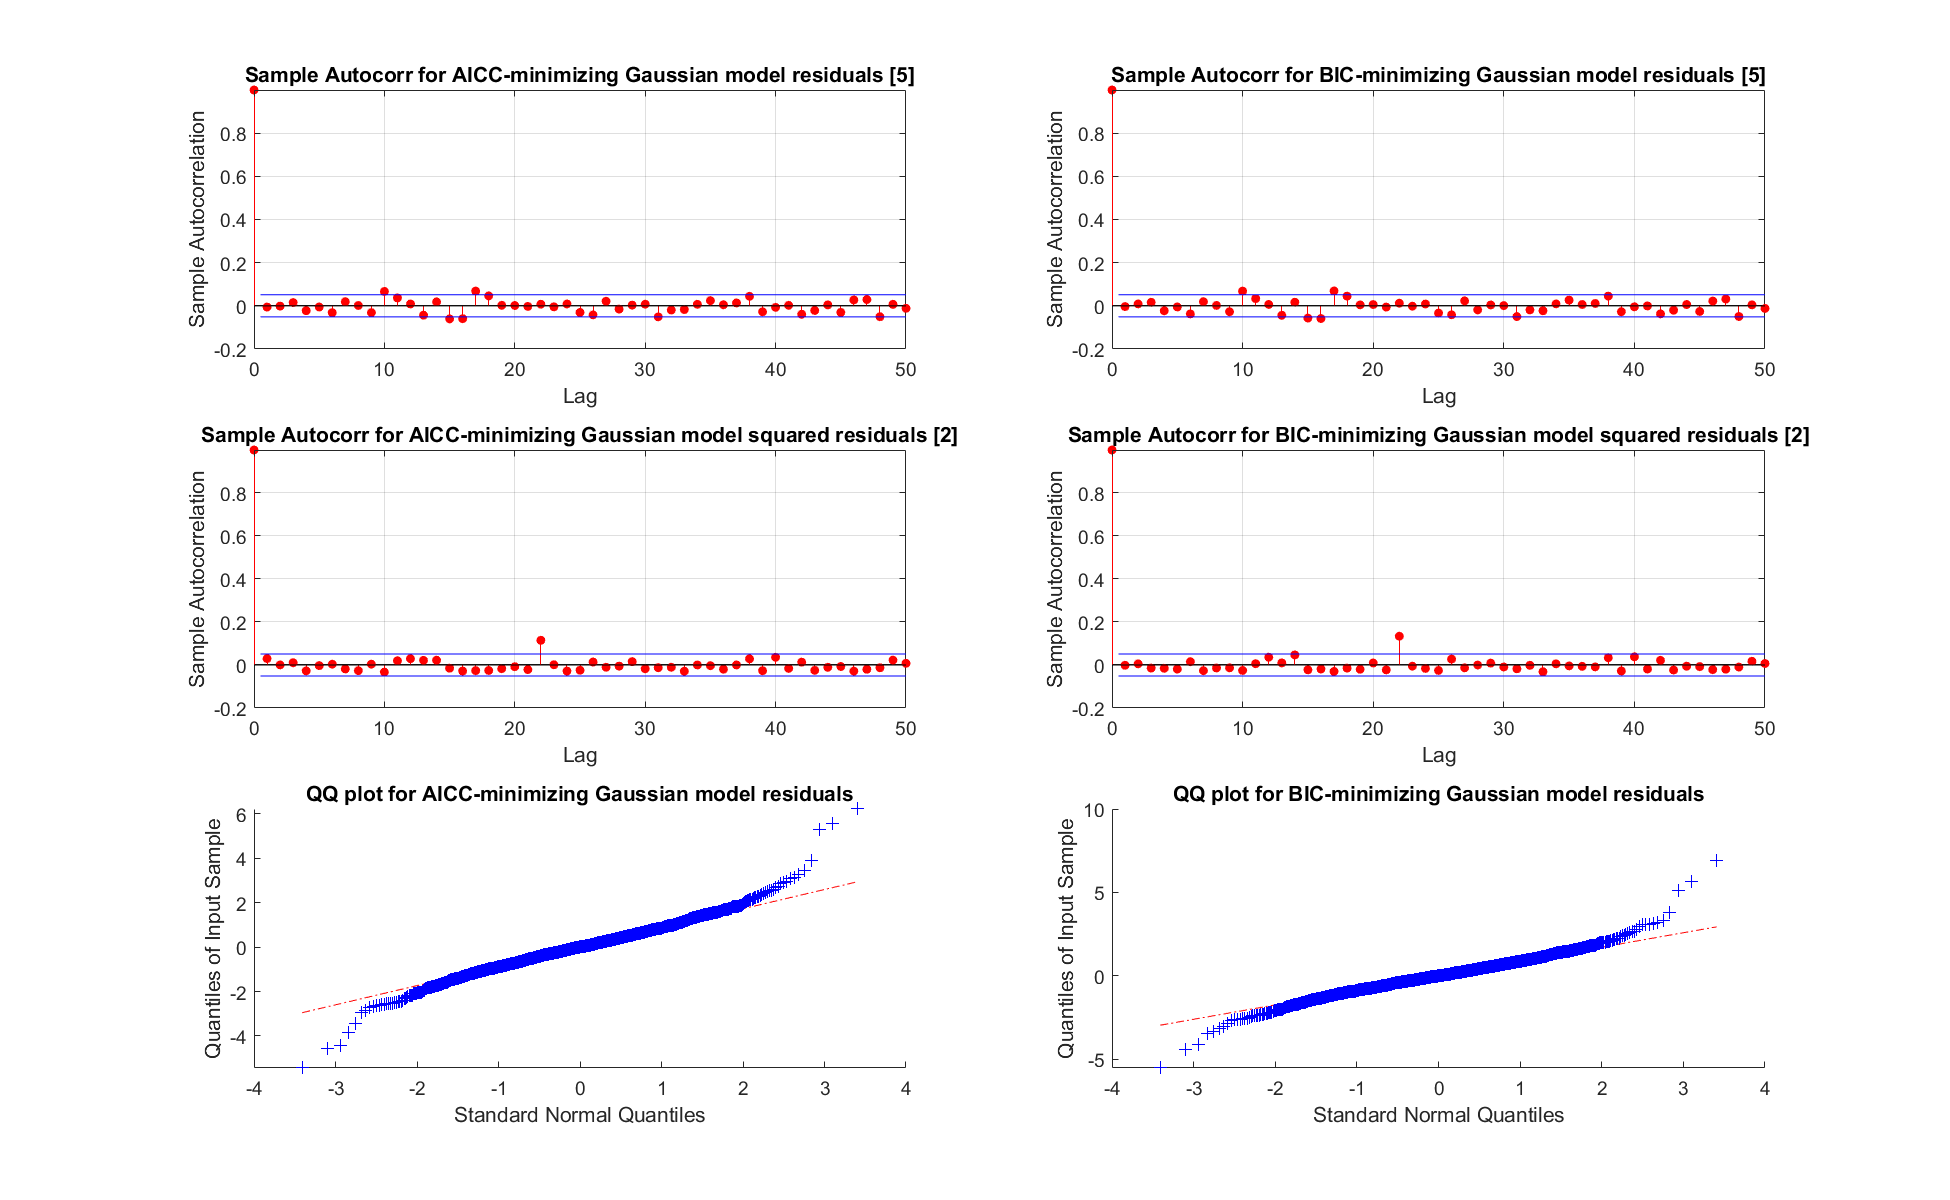

close all
set(gcf,'Position',[100, 100, 1300, 800])

cond_var_AICC = infer(best_GARCH_mdl_Gauss_AICC, trainX);
cond_var_BIC = infer(best_GARCH_mdl_Gauss_BIC, trainX);
res_AICC = (trainX - best_GARCH_mdl_Gauss_AICC.Offset) ./ sqrt(cond_var_AICC);
res_BIC = (trainX - best_GARCH_mdl_Gauss_BIC.Offset) ./ sqrt(cond_var_BIC);

subplot(3,2,1)
[acf, lags, bounds] = autocorr(res_AICC,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_AICC,50)
title(['Sample Autocorr for AICC-minimizing Gaussian model residuals [' num2str(num_significant) ']'])

subplot(3,2,3)
[acf, lags, bounds] = autocorr(res_AICC.^2,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_AICC.^2,50)
title(['Sample Autocorr for AICC-minimizing Gaussian model squared residuals [' num2str(num_significant) ']'])

subplot(3,2,5)
qqplot(res_AICC)
title('QQ plot for AICC-minimizing Gaussian model residuals')

subplot(3,2,2)
[acf, lags, bounds] = autocorr(res_BIC,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_BIC,50)
title(['Sample Autocorr for BIC-minimizing Gaussian model residuals [' num2str(num_significant) ']'])

subplot(3,2,4)
[acf, lags, bounds] = autocorr(res_BIC.^2,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_BIC.^2,50)
title(['Sample Autocorr for BIC-minimizing Gaussian model squared residuals [' num2str(num_significant) ']'])

subplot(3,2,6)
qqplot(res_BIC)
title('QQ plot for BIC-minimizing Gaussian model residuals')

If the model is correct the residuals should follow the underlying assumed distribution of the model (in this case, Gaussian).

The QQ-plots should follow a straight line if the residuals are normally distributed as we are fitting a GARCH process driven by Gaussian noise. There are some outliers on either end, indicating our residuals follow the central part of the assumed distribution but have heavier tails.

Looking at the Sample autocorrelation we see that there are few significant values, indicating that there is little autocorrelation among the residuals.

A normal distribution might not be appropriate here.

### 6)

Repeat the previous two tasks, assuming now that the noise follows a *t*-distribution (and taking $K$ as the maximal order of the ARMA models with *t*-distribution noise fitted in Task 3), so that you end up with four candidate models.

clearvars EstMdl numParam_garch logL_garch
Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
i = 1;
K = max_order_t;
qp_garch = [];
for p = 1:K
    for q = 1:K
        mdl_temp = garch('GARCHLags',1:q,'ARCHLags',1:p,'Distribution',struct('Name','t','DoF',nan));
        [EstMdl(i), ~, logL_garch(i), ~] = estimate(mdl_temp, trainX, 'Display', 'off', 'Options', Options);
        results = summarize(EstMdl(i));
        numParam_garch(i) = sum(results.Table.Value ~= 0) - 1; % removing DoF
        DoF(i) = results.Table.Value(end);
        qp_garch = [qp_garch,  [q; p]];
        i = i + 1;
    end
end
q_garch = qp_garch(1,:);
p_garch = qp_garch(2,:);

AICC_garch = calculateAICC(length(trainX), numParam_garch, logL_garch); % both defined at end of file
BIC_garch = -2*logL_garch + numParam_garch*log(length(trainX));

i_AICC = find(AICC_garch==min(AICC_garch));
i_BIC = find(BIC_garch==min(BIC_garch));

best_GARCH_mdl_t_AICC = EstMdl(i_AICC);
best_GARCH_mdl_t_BIC = EstMdl(i_BIC);
disp(["Model which minimizes [BD]'s AICC:" EstMdl(i_AICC).Description; "Model which minimizes hint's BIC:" EstMdl(i_BIC).Description])

    "Model which minimizes [BD]'s AICC:"    "GARCH(2,2) Conditional Variance Model (t Distribution)"
    "Model which minimizes hint's BIC:"     "GARCH(1,1) Conditional Variance Model (t Distribution)"



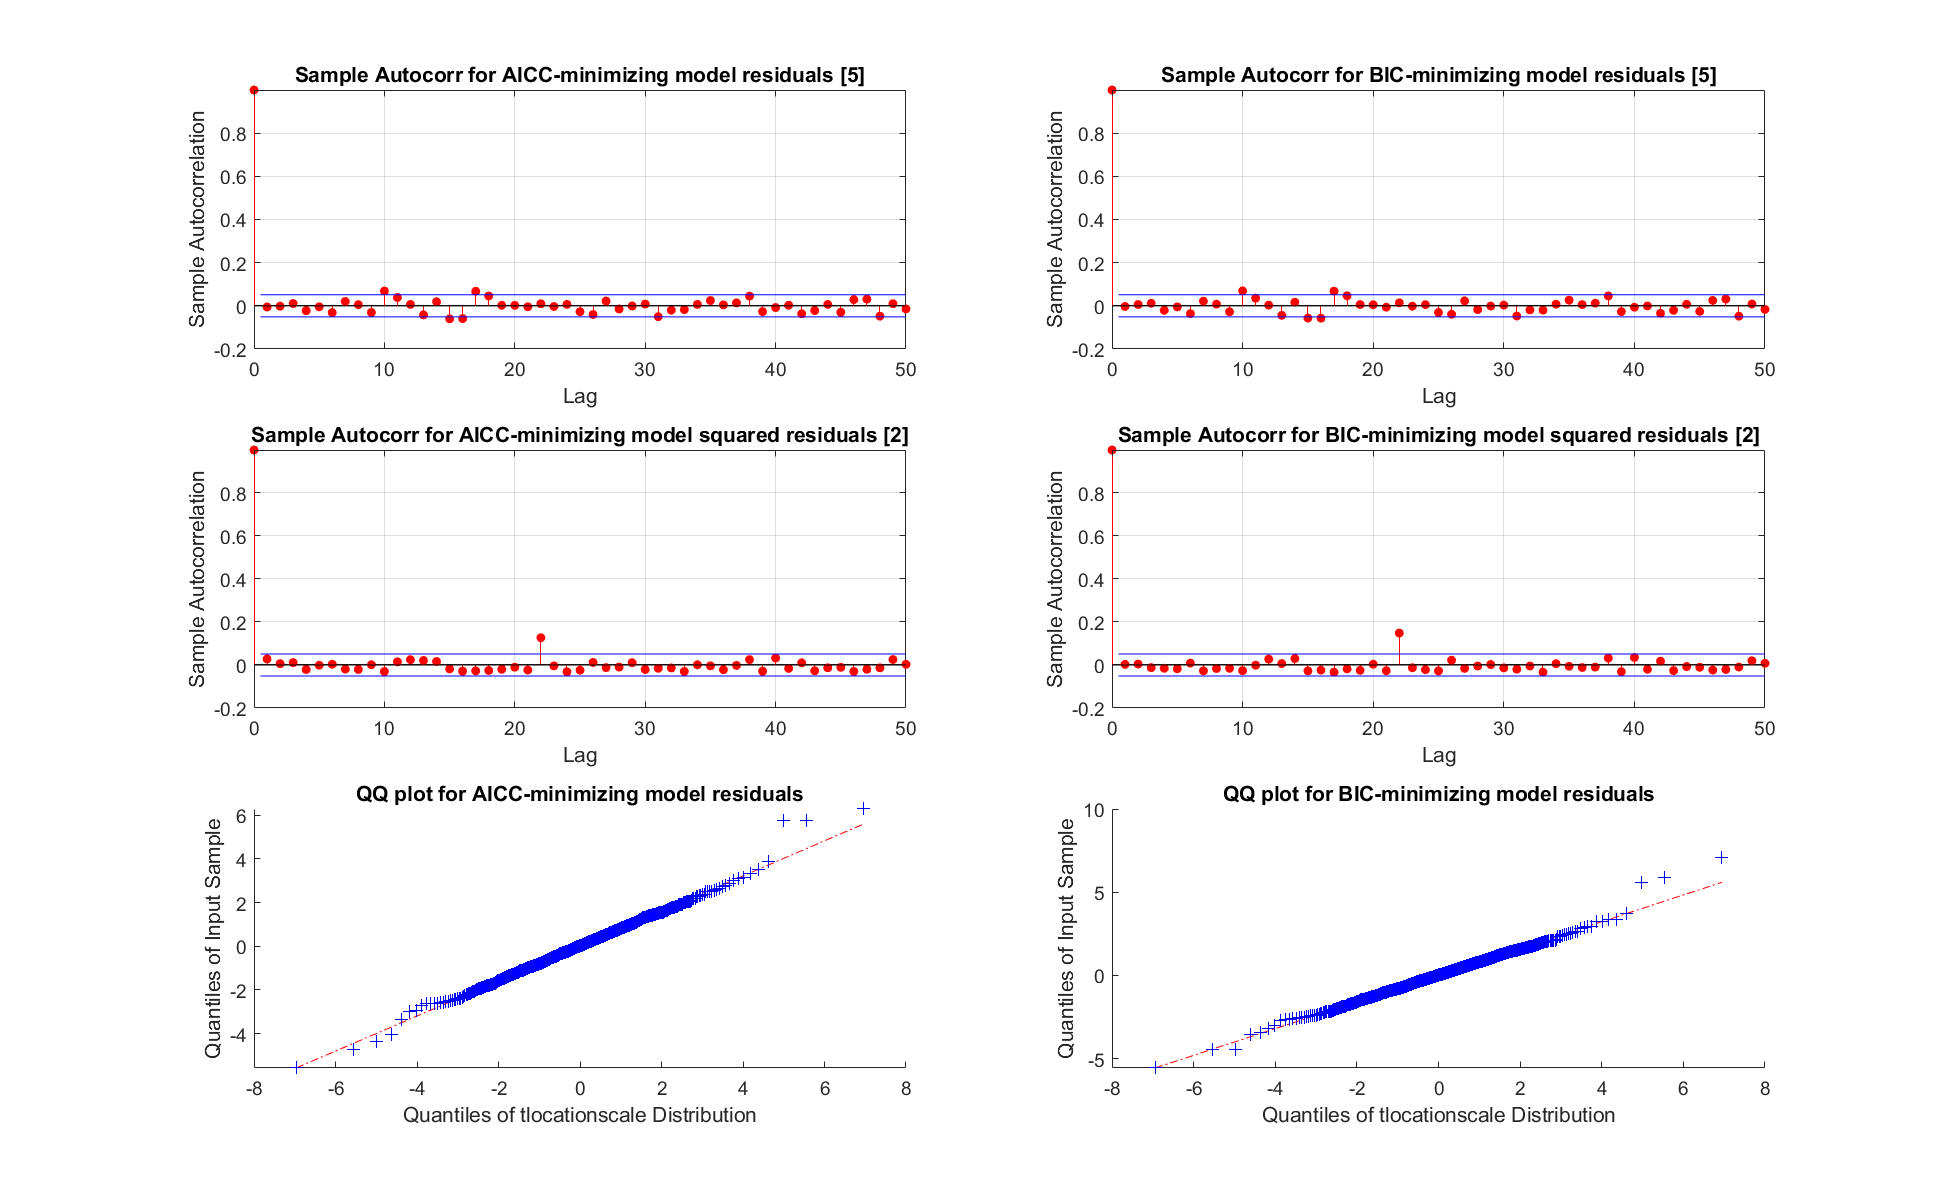

close all
set(gcf,'Position',[100, 100, 1300, 800])
t_dist_AICC = makedist('tLocationScale','nu',DoF(i_AICC));
t_dist_BIC = makedist('tLocationScale','nu',DoF(i_BIC));

cond_var_AICC = infer(best_GARCH_mdl_t_AICC, trainX);
cond_var_BIC = infer(best_GARCH_mdl_t_BIC, trainX);
res_AICC = (trainX - best_GARCH_mdl_t_AICC.Offset) ./ sqrt(cond_var_AICC);
res_BIC = (trainX - best_GARCH_mdl_t_BIC.Offset) ./ sqrt(cond_var_BIC);

subplot(3,2,1)
[acf, lags, bounds] = autocorr(res_AICC,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_AICC,50)
title(['Sample Autocorr for AICC-minimizing model residuals [' num2str(num_significant) ']'])

subplot(3,2,3)
[acf, lags, bounds] = autocorr(res_AICC.^2,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_AICC.^2,50)
title(['Sample Autocorr for AICC-minimizing model squared residuals [' num2str(num_significant) ']'])

subplot(3,2,5)
qqplot(res_AICC, t_dist_AICC)
title('QQ plot for AICC-minimizing model residuals')

subplot(3,2,2)
[acf, lags, bounds] = autocorr(res_BIC,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_BIC,50)
title(['Sample Autocorr for BIC-minimizing model residuals [' num2str(num_significant) ']'])

subplot(3,2,4)
[acf, lags, bounds] = autocorr(res_BIC.^2,50);
num_significant = sum(abs(acf)-bounds(1) > 0);
autocorr(res_BIC.^2,50)
title(['Sample Autocorr for BIC-minimizing model squared residuals [' num2str(num_significant) ']'])

subplot(3,2,6)
qqplot(res_BIC, t_dist_BIC)
title('QQ plot for BIC-minimizing model residuals')

If the residuals follow a t-distribution, we would expect a straight line. The QQ-plots here look better than for the normal distribution. We have a only several outliers.

Looking at the Sample autocorrelation we see that we have some minor outliers for training data of X, and as there are more than 5% of the number of lags outside, that could indicate that we have some correlation left. The squared residuals looks better, with only one lag outside of the bounds, indicating that we have a good model for the data.

Compared to the gained model in task 3 for t-distribution, one of the models correspond with the gained result in this task; GARCH(2,2)).

### 7)

Estimate ${\textrm{VaR}}_t$ and evaluate the estimates for $t=1527,\ldotp \ldotp \ldotp ,1751$by following these steps for each of the four candidate models obtained in Tasks 4 and 6, as well as the four GARCH models obtained in Task 3:

- Report the distribution of $X_t$ given $\left(X_s ,V_s ,s<t\right)$ including its parameters (this will either be a Gaussian or a (generalized) *t*-distribution

- For each $t=1527,\ldotp \ldotp \ldotp ,1751$ of the test data set, compute ${\textrm{VaR}}_t$ given $\left(X_S ,V_s ,s<t\right)$ using (1) for $p=0\ldotp 1,0\ldotp 05,0\ldotp 01\ldotp$ Do not reestimate parameters of the models at each time $t,$ but use the observations $\left(X_2 ,\ldotp \ldotp \ldotp ,X_{t-1} \right)$ to update the conditional variances as needed

- Count the number of $\textrm{VaR}$ breaches, i.e., for $t=1577,\ldotp \ldotp \ldotp ,1751,$ count the number of times that $V_t -V_{t-1} \le {\textrm{VaR}}_t$

After doing this, also compute ${\textrm{VaR}}_t$ under the simple model that $X_t ~N\left(0,\hat{\;\sigma_{t-1}^2 } \right)$, where $\hat{\;\sigma_{t-1}^2 }$is the sample variance of $X_2 ,X_3 ,\ldotp \ldotp \ldotp ,X_{t-1}$ and count the number of breaches as above.

Report the number of breaches for each *p* and each of the candidate models. Based on the outcome of this experiment, what model for the estimation of ${\textrm{VaR}}_t$ would you recommend for this stock and why? (You are welcome to implement alternative models for the returns if you can find one that appears to fit the data better than the ones above. If so, you need to make a careful description of it and report your results in detail).

**We now have the following models that we want to perform the final evaluation on;**

From task 3: GARCH(3,2) gaussian, GARCH(1,2) t-dist, GARCH(2,2) t-dist, GARCH(3,2) t-dist.

From task 4: GARCH(2,2) gaussian (same for AICC and BIC)

From task 5: GARCH(2,2) t-dist (same for AICC and BIC)

# @Matthias:

Wtf does "update the conditional variances as needed" mean?

models = {};

%Create gaussian model from task 3
mdl_temp = garch('GARCHLags',1:3,'ARCHLags',1:2,'Offset',mean(trainX));
[models{1}, ~, ~] = estimate(mdl_temp, trainX, 'Display', 'off', 'Options', Options);

for i = 2:4
    mdl_temp = garch('GARCHLags',1:(i-1),'ARCHLags',1:2,'Distribution',struct('Name','t','DoF',nan));
    [EstMdl, ~, ~] = estimate(mdl_temp, trainX, 'Display', 'off', 'Options', Options);
    models{i} = EstMdl;
end
% i{5} = 

candidate_GARCH_models = [best_GARCH_mdl_Gauss_AICC, best_GARCH_mdl_Gauss_BIC, best_GARCH_mdl_t_AICC, best_GARCH_mdl_t_BIC];
% for i = 1:length(candidate_ARMA_models):
%     for j = 1:length(candidate_ARMA_models(j).Pro)
% end


### Appendix: Functions

function AICC = calculateAICC(n, M, logL)
    factor = (2*n*M) ./ (n-M-1);
    AICC = -2*logL + factor;
end

function BIC = calculateBIC(n, p, q, var, X, M, which)
    if which == 'pq' % include zero-valued parameters
        left = (n-p-q) .* log( (n.*var) ./ (n-p-q) );
        middle = n * (1 + log(sqrt(2*pi)));
        right = (p+q) .* log((sum(X.^2) - n.*var) ./ (p+q));
        BIC = left + middle + right;
        
    else % do not include zero-valued parameters
        left = (n-M) .* log( (n.*var) ./ (n-M));
        middle = n * (1 + log(sqrt(2*pi)));
        right = M .* log((sum(X.^2) - n.*var) ./ M);
        BIC = left + middle + right;
    end
end